# Interface para o método de ODE23 e ODE45

CHAMADA DE FUNÇÕES:

    ODE23

    ODE45

    dsolve

26/03/2021  Arménio Correia  armenioc@isec.pt

Trabalho realizado por:(23/04/2021)

        Diogo Silva - 2020138438 - a2020138438@isec.pt

        Hugo Ferreira - 2020128305 - 2020128305@isec.pt

        Rúben Mendes  - 2020138473 - a2020138473@isec.pt

clc
clear

syms y(t)

strF = input('f(t,y) = ','s');
f = @(t,y)eval(vectorize(strF));

disp('----- Método ODE23 e ODE45 ------ ');

----- Método ODE23 e ODE45 ------ 


a  = str2num(input('a = ','s'));
b  = str2num(input('b = ','s'));
n  = str2num(input('n = ','s'));
y0 = str2num(input('y0 = ','s'));

yODE23 = NODE23(f,a,b,n,y0)

yODE23 = 	1.0e+04 *

    0.0006    0.0016    0.0056    0.0278    0.1896    1.7777


yODE45 = NODE45(f,a,b,n,y0)

yODE45 = 	1.0e+04 *

    0.0006    0.0016    0.0056    0.0279    0.1904    1.7889




sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = 6\,{\mathrm{e}}^{t^{2}}\,{\mathrm{e}}^{-1}$$

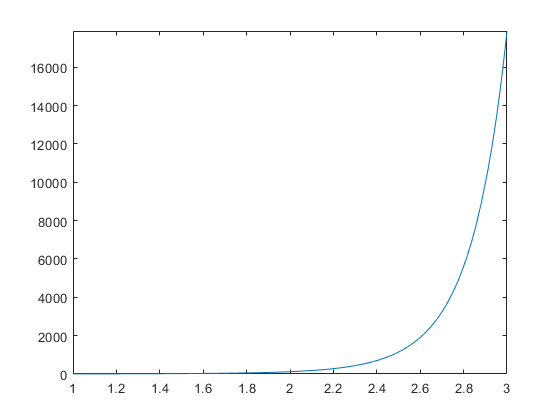

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroODE23 = abs(yExata-yODE23);
erroODE45 = abs(yExata-yODE45);
disp('----- Tabela de Valores ------ ');

----- Tabela de Valores ------ 


tabela = [t.',yExata.',yODE23.',yODE45.',erroODE23.',erroODE45.'];
array2table(tabela,"VariableNames",{'t','Exata','ODE23','ODE45','Erro ODE23','Erro ODE45'})

ans = 6×6 table
     t     Exata     ODE23     ODE45     Erro ODE23    Erro ODE45
    ___    ______    ______    ______    __________    __________

      1         6         6         6    1.7764e-15    1.7764e-15
    1.4     15.67     15.66    15.671       0.01016    0.00033439
    1.8     56.36    56.271    56.363      0.088996     0.0030818
    2.2    279.15    278.38    279.18        0.7768      0.030709
    2.6    1904.1    1895.9    1904.4        8.1435       0.33723
      3     17886     17777     17889        109.14        2.7609



disp('----- Gráfico de Soluções ------ ');

----- Gráfico de Soluções ------ 


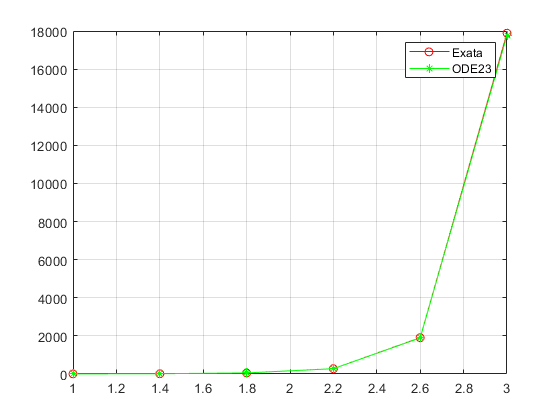

plot(t,yExata,"-ro")
hold on
plot(t,yODE23,"-g*")
hold off
grid on
legend('Exata','ODE23')

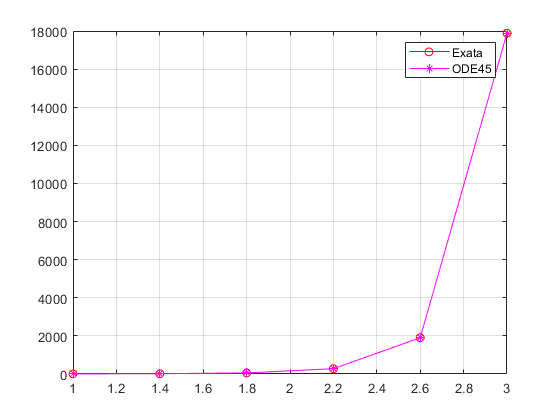



plot(t,yExata,"-ro")
hold on
plot(t,yODE45,"-m*")
hold off
grid on
legend('Exata','ODE45')